# Dinamica Veicolo Autobilanciato - gruppo Calegari

## Setup iniziale dell'ambiente

clear
clc
digits(4)

## Definizione delle variabili simboliche

syms t; % Tempo
syms T; % Energia cinetica del sistema
syms U; % Energia potenziale del sistema
syms alpha; % Angolo di offset (inclinazione utente) che sposta in avanti il baricentro

syms q_1 q_1_p q_1_pp;
syms q_2 q_2_p q_2_pp; % Coordinate libere
syms phi(t); % Posizione carrello / r
vel = diff(phi, t); % Velocità carello / r
syms theta(t); % Angolo inclinazione
vel_ang = diff(theta, t); % Vel angolare
syms C_m C_m_star; % Forza esterna
syms u;%input sistema dinamico

## Definizione masse e gravità

Masse espresse tutte in [kg].

% Massa singola ruota
m_r = sym('3');
% Massa asta
m_a = sym('3.5');
% Massa uomo
m_c = sym('70');

% Massa carello(base) + batterie
m_b = sym('34.4');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante di accelerazione di gravità
g = sym('9.80665');

## Definizione delle altezze

Dimensioni espresse tutte in [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Altezza uomo
h_c = sym('1.77');

% Raggio ruota
r = sym('0.22');

## Definizione inerzie

Inerzie espresse in [$\textrm{kg}\bullet m^2$]

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo espressa rispetto all'asse principale
altezza_cm = h_c * 100; % Altezza dell'uomo espressa in [cm]
J_c = (1732353 * altezza_cm + 619298*2.20462*m_c - 277625773) * (10^-7);

% Inerzia della singola ruota
J_r = sym('0.1452');

## Definizione delle costanti geometriche $\alpha \;e\;\beta \;$e rapporti di trasmissione

Si definiscono i parametri geometrici d'interesse come nell'immagine, la quale si trova in una condizione di $\theta =0\ldotp$

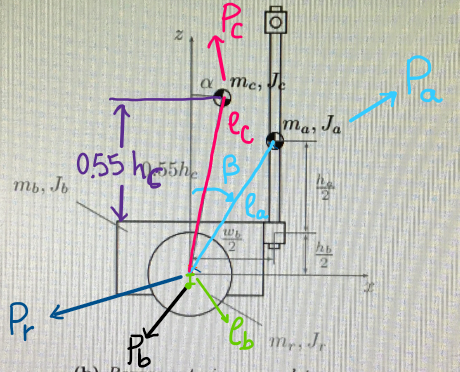

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;

% Al baricentro del corpo umano vado ad aggiungere l'altezza della base
% sulla quale esso appoggia i piedi (è una quota quindi da aggiungere)

l_c = 0.55 * h_c + h_b * 0.5;
l_b = 0.1;
l_a = sqrt((temp_1)^2 + (temp_2)^2);
beta = atan(temp_2/temp_1);

Per il rapporto di trasmissione andiamo a calcolarlo come moltiplicazione tra il rapporto trasmissivo della trasmissione epicicloidale e quello della cinghia.

Nello specifico il rapporto della cinghia andiamo a calcolarlo come:

num_denti_driver = 22;
num_denti_driven = 26;
tau_cinghia = num_denti_driver / num_denti_driven;
tau = 0.1 * tau_cinghia;

## Calcolo componenti dinamiche e potenziali per ogni corpo rigido del sistema

Per il calcolo delle equazioni dinamiche del sistema siamo andati a considerare ogni singolo corpo rigido componente il sistema, calcolandone le grandezze fisiche di posizione e velocità, con un approccio cartesiano. 

Nello specifico abbiamo considerato il sistema composto da:

- Asta ($P_a$)

- Utente a bordo dello chassis ($P_c$)

- Chassis (o base) ($P_b$)

- Ruota ($P_r$) che poi sarà considerata con un contributo doppio, essendo 2 le ruote del sistema

Per ognuno di questi corpi rigidi siamo andati appunto a calcolare:

- Coordinate spaziali nel sistema di riferimento XZ, con l'aggiunta delle coordinate angolari $$\rightarrow$$ vettore 3 x 1

- Vettore delle velocità $$\rightarrow$$ vettore 3 x 1

- Matrice delle masse $$\rightarrow$$ matrice 3 x 3

- Energia cinetica dello specifico corpo rigido $$\rightarrow$$ $T=\frac{1}{2\;}\bullet V^T \bullet M\bullet V$

- Energia potenziale dello specifico corpo rigido$$\rightarrow$$ $U$

- Lagrangiana dello specifico corpo rigido $$\rightarrow$$ $L=T-U$

### Asta $P_a$

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta]

$$P\_a(t) = \left(\begin{array}{c} 0.8\,\sin\left(\theta \left(t\right)\right)+0.22\,\varphi \left(t\right)\\ 0.8\,\cos\left(\theta \left(t\right)\right)\\ \theta \left(t\right) \end{array}\right)$$

V_a = diff(P_a, t)

$$V\_a(t) = \left(\begin{array}{c} 0.8\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -0.8\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a + m_a *l_a^2] % Matrice delle masse/inerzie

$$M\_a = \left(\begin{array}{ccc} 3.5 & 0 & 0\\ 0 & 3.5 & 0\\ 0 & 0 & 2.407 \end{array}\right)$$

T_a = collect(simplify((1/2 * transpose(V_a) * M_a * V_a), 'Steps', 50))

$$T\_a(t) = 0.0847\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+2.323\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+0.616\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

U_a = m_a * g * l_a * cos(theta+beta);
L_a = collect(simplify((T_a - U_a), 'Steps', 50));

### Utente  $P_c$

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]

$$P\_c(t) = \left(\begin{array}{c} 1.073\,\sin\left(\alpha +\theta \left(t\right)\right)+0.22\,\varphi \left(t\right)\\ 1.073\,\cos\left(\alpha +\theta \left(t\right)\right)\\ \alpha +\theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t)

$$V\_c(t) = \left(\begin{array}{c} 1.073\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ -1.073\,\sin\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c + m_c * l_c^2]

$$M\_c = \left(\begin{array}{ccc} 70 & 0 & 0\\ 0 & 70 & 0\\ 0 & 0 & 93.13 \end{array}\right)$$

T_c = collect(simplify((1/2 * transpose(V_c) * M_c * V_c), 'Steps', 50))

$$T\_c(t) = 1.694\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+86.9\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-0.000458\,{\cos\left(\alpha +\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+16.53\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

U_c = m_c * g * l_c * cos(alpha+theta);
L_c = collect(simplify((T_c - U_c), 'Steps', 50))

$$L\_c(t) = 1.694\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-736.9\,\cos\left(\alpha +\theta \left(t\right)\right)+86.9\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-0.000458\,{\cos\left(\alpha +\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+16.53\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

### Chassis (o base)  $P_b$

Come da specifiche, il baricentro della base risulta essere posizionato ad una quota differente rispetto al centro del sistema di coordinate preso come riferimento. Per questo motivo che il suo contributo cinetico e potenziale dipende da quale inclinazione presenta lo chassis stesso, ovvero dall'angolo caratteristico del sistema $\theta \;$. Questo fatto è messo in evidenza nell'immagine seguente:

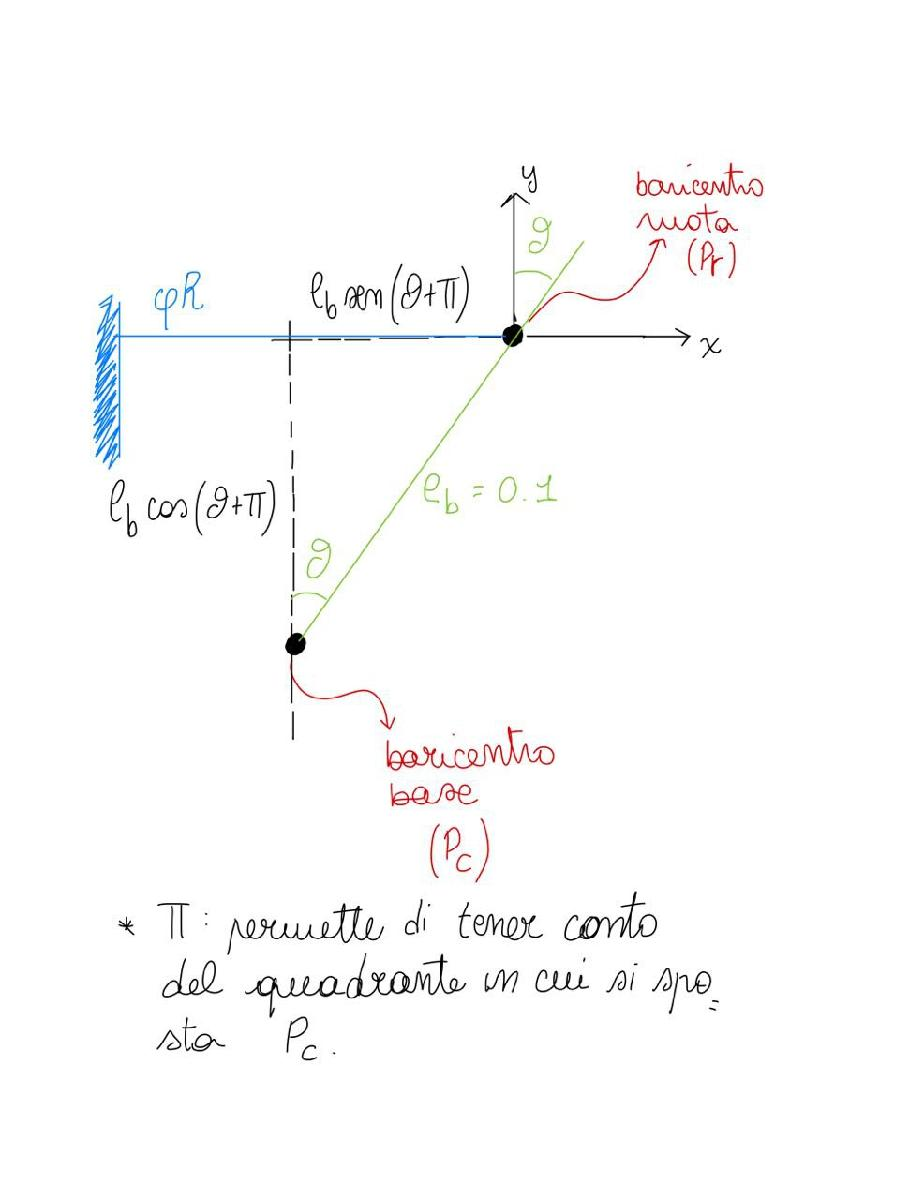

P_b = [phi*r + l_b*sin(pi+theta); l_b*cos(pi+theta); theta]

$$P\_b(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)-\frac{\sin\left(\theta \left(t\right)\right)}{10}\\ -\frac{\cos\left(\theta \left(t\right)\right)}{10}\\ \theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t)

$$V\_b(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)}{10}\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b + m_b*l_b^2]

$$M\_b = \left(\begin{array}{ccc} 34.4 & 0 & 0\\ 0 & 34.4 & 0\\ 0 & 0 & 1.011 \end{array}\right)$$

T_b = collect(simplify((1/2 * transpose(V_b) * M_b * V_b), 'Steps', 50))

$$T\_b(t) = 0.8325\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+0.6773\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-0.7568\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

U_b = m_b * g * l_b * cos(pi+theta);
L_b = collect(simplify((T_b - U_b), 'Steps', 50))

$$L\_b(t) = 33.73\,\cos\left(\theta \left(t\right)\right)+0.8325\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+0.6773\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-0.7568\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)$$

### Ruota $P_r$

P_r = [phi*r; 0; phi]

$$P\_r(t) = \left(\begin{array}{c} 0.22\,\varphi \left(t\right)\\ 0\\ \varphi \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} 0.22\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} 3 & 0 & 0\\ 0 & 3 & 0\\ 0 & 0 & 0.1452 \end{array}\right)$$

T_r = collect(simplify((1/2 * transpose(V_r) * M_r * V_r), 'Steps', 50))

$$T\_r(t) = 0.1452\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

U_r = 0;
L_r = collect(simplify((T_r - U_r), 'Steps', 50))

$$L\_r(t) = 0.1452\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

### Lagrangiana dell'intero sistema

Per confronto, andiamo a definire in prima battuata l'energia cinetica e potenziale totale dell'intero sistema:

T_totale = collect(simplify((T_a + T_b + T_c + 2 * T_r), 'Steps', 50))

$$T\_totale(t) = \begin{array}{l} 2.902\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+89.9\,\sigma_{1}-0.000229\,\cos\left(2\,\alpha +2\,\theta \left(t\right)\right)\,\sigma_{1}-0.1408\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+16.53\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

U_totale = simplify((U_a + U_b + U_c + 2 * U_r), 'Steps', 50)

$$U\_totale(t) = 736.9\,\cos\left(\alpha +\theta \left(t\right)\right)-6.276\,\cos\left(\theta \left(t\right)\right)$$

Andiamo ora a sommare tutte le singole lagrangiane dei vari corpi rigidi (considerando doppio l'apporto delle ruote).

L = collect(simplify((2*L_r + L_c+ L_a + L_b), 'Steps', 50))

$$L(t) = \begin{array}{l} 6.276\,\cos\left(\theta \left(t\right)\right)-736.9\,\sigma_{1}+2.902\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+89.9\,\sigma_{2}-0.000229\,\cos\left(2\,\alpha +2\,\theta \left(t\right)\right)\,\sigma_{2}-0.1408\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+16.53\,\sigma_{1}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\alpha +\theta \left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}) % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

$$L\_q(t) = 6.276\,\cos\left(q_{2}\right)-736.9\,\cos\left(\alpha +q_{2}\right)-0.000229\,{q_{2,p}}^{2}\,\cos\left(2\,\alpha +2\,q_{2}\right)+2.902\,{q_{1,p}}^{2}+89.9\,{q_{2,p}}^{2}-0.1408\,q_{1,p}\,q_{2,p}\,\cos\left(q_{2}\right)+16.53\,q_{1,p}\,q_{2,p}\,\cos\left(\alpha +q_{2}\right)$$

## Equazioni del moto

Calcoliamo ora le equazioni del moto, considerando, come coordinate libere

- 
$$\phi =q_{1\;} =\textrm{angolo}\;\textrm{di}\;\textrm{rotazione}\;\textrm{delle}\;\textrm{ruote}$$


- 
$$\theta =q_2 =\textrm{inclinazione}\;\textrm{chassis}$$


Utilizziamo questa formulazione:


$$\frac{d}{\textrm{dt}}\left(\frac{\partial }{\partial \dot{q} }L\right)-\frac{\partial }{\partial q}L=\textrm{torque}\;$$


### Calcolo equazioni del moto rispetto a phi ($$q_1$$$=\phi \;$) 

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);
C_m_star = 1/tau*C_m

$$C\_m\_star = \frac{130\,C_{m}}{11}$$

E_L_phi = collect(simplify((dL_dvel_dt - dL_dphi == -C_m_star), 'Steps', 50))

$$E\_L\_phi(t) = 130.0\,C_{m}+181.9\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+1.549\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+63.83\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)=1.549\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+181.9\,\sin\left(\alpha +\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}$$

### Calcolo equazioni del moto rispetto a theta ($q_2$$=\theta \;$) 

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(simplify((dL_dvel_ang_dt - dL_dtheta ==  C_m), 'Steps', 50))

$$E\_L\_theta(t) = \begin{array}{l} 6.276\,\sin\left(\theta \left(t\right)\right)+0.000458\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+16.53\,\cos\left(\alpha +\theta \left(t\right)\right)\,\sigma_{3}+179.8\,\sigma_{2}=C_{m}+736.9\,\sin\left(\alpha +\theta \left(t\right)\right)+0.000458\,\cos\left(\sigma_{1}\right)\,\sigma_{2}+0.1408\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}\\ \mathrm{where}\\ \sigma_{1}=2\,\alpha +2\,\theta \left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

## Risoluzione delle equazioni del moto

Risolviamo ora le due equazioni del moto, ottenendo le variabili $\;\overset{\ldotp \ldotp }{\phi \;}$e $\overset{\ldotp \ldotp }{\theta \;}$.

acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q_1_pp,q_2_pp}), subs(E_L_phi, {acc,acc_ang},{q_1_pp,q_2_pp})];

%To ensure the order of the returned solutions, specify the variables vars. 
%For example, the call [b,a] = solve(eqns,b,a) assigns the solutions for a to a and the solutions for b to b.
S = solve(eqns, q_1_pp, q_2_pp)

S = struct with fields:
    q_1_pp: [1×1 sym]
    q_2_pp: [1×1 sym]


phi2 = S.q_1_pp

$$phi2 = \begin{array}{l} \frac{0.08\,\left(2.922e+13\,C_{m}+1.215e+10\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+1.675e+14\,\sigma_{1}\,\sigma_{3}-4.087e+13\,\sigma_{3}\,\sigma_{2}+2.273e+11\,C_{m}\,\sigma_{1}-1.427e+12\,\sigma_{1}\,\sin\left(\theta \left(t\right)\right)-1.427e+12\,\sigma_{3}\,\cos\left(\theta \left(t\right)\right)+3.481e+11\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-7.442e+7\,C_{m}\,\cos\left(\sigma_{4}\right)-1.936e+9\,C_{m}\,\cos\left(\theta \left(t\right)\right)-8.867e+5\,\cos\left(\sigma_{4}\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+8.867e+5\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\sigma_{4}\right)\,\sigma_{2}-1.041e+8\,\sigma_{1}\,\sin\left(\sigma_{4}\right)\,\sigma_{2}+1.041e+8\,\sigma_{3}\,\cos\left(\sigma_{4}\right)\,\sigma_{2}\right)}{3.006e+11\,{\sigma_{1}}^{2}-5.121e+9\,\sigma_{1}\,\cos\left(\theta \left(t\right)\right)+2.181e+7\,{\cos\left(\theta \left(t\right)\right)}^{2}+2.924e+6\,\cos\left(\sigma_{4}\right)-1.148e+12}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\alpha +\theta \left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\sin\left(\alpha +\theta \left(t\right)\right)\\ \sigma_{4}=2.0\,\alpha +2.0\,\theta \left(t\right) \end{array}$$

theta2 = S.q_2_pp

$$theta2 = \begin{array}{l} -\frac{1.0\,\left(6.384e+9\,C_{m}+4.704e+12\,\sigma_{3}-4.006e+10\,\sin\left(\theta \left(t\right)\right)+2.149e+11\,C_{m}\,\sigma_{1}-2.924e+6\,\sin\left(\sigma_{4}\right)\,\sigma_{2}-1.83e+9\,C_{m}\,\cos\left(\theta \left(t\right)\right)-2.181e+7\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-3.006e+11\,\sigma_{1}\,\sigma_{3}\,\sigma_{2}+2.56e+9\,\sigma_{1}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+2.56e+9\,\sigma_{3}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}\right)}{3.006e+11\,{\sigma_{1}}^{2}-5.121e+9\,\sigma_{1}\,\cos\left(\theta \left(t\right)\right)+2.181e+7\,{\cos\left(\theta \left(t\right)\right)}^{2}+2.924e+6\,\cos\left(\sigma_{4}\right)-1.148e+12}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\alpha +\theta \left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\sin\left(\alpha +\theta \left(t\right)\right)\\ \sigma_{4}=2.0\,\alpha +2.0\,\theta \left(t\right) \end{array}$$

Le due seguenti equazioni simboliche rappresentano le **equazioni non lineari del modello dinamico.**

syms u_star
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u})

$$theta2\_differenziabile = \begin{array}{l} -\frac{1.0\,\left(6.384e+9\,u+4.704e+12\,\sin\left(\alpha +q_{2}\right)-4.006e+10\,\sin\left(q_{2}\right)-2.924e+6\,{q_{2,p}}^{2}\,\sin\left(\sigma_{1}\right)+2.149e+11\,u\,\cos\left(\alpha +q_{2}\right)-1.83e+9\,u\,\cos\left(q_{2}\right)-3.006e+11\,{q_{2,p}}^{2}\,\cos\left(\alpha +q_{2}\right)\,\sin\left(\alpha +q_{2}\right)+2.56e+9\,{q_{2,p}}^{2}\,\cos\left(\alpha +q_{2}\right)\,\sin\left(q_{2}\right)+2.56e+9\,{q_{2,p}}^{2}\,\sin\left(\alpha +q_{2}\right)\,\cos\left(q_{2}\right)-2.181e+7\,{q_{2,p}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)\right)}{3.006e+11\,{\cos\left(\alpha +q_{2}\right)}^{2}-5.121e+9\,\cos\left(\alpha +q_{2}\right)\,\cos\left(q_{2}\right)+2.181e+7\,{\cos\left(q_{2}\right)}^{2}+2.924e+6\,\cos\left(\sigma_{1}\right)-1.148e+12}\\ \mathrm{where}\\ \sigma_{1}=2.0\,\alpha +2.0\,q_{2} \end{array}$$

phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,C_m},{q_1 q_1_p q_2 q_2_p u })

$$phi2\_differenziabile = \begin{array}{l} \frac{0.08\,\left(2.922e+13\,u+3.481e+11\,{q_{2,p}}^{2}\,\sin\left(q_{2}\right)+1.215e+10\,\cos\left(q_{2}\right)\,\sin\left(q_{2}\right)+2.273e+11\,u\,\cos\left(\alpha +q_{2}\right)+1.675e+14\,\cos\left(\alpha +q_{2}\right)\,\sin\left(\alpha +q_{2}\right)-7.442e+7\,u\,\cos\left(\sigma_{1}\right)-1.936e+9\,u\,\cos\left(q_{2}\right)-4.087e+13\,{q_{2,p}}^{2}\,\sin\left(\alpha +q_{2}\right)-1.427e+12\,\cos\left(\alpha +q_{2}\right)\,\sin\left(q_{2}\right)-1.427e+12\,\sin\left(\alpha +q_{2}\right)\,\cos\left(q_{2}\right)-1.041e+8\,{q_{2,p}}^{2}\,\cos\left(\alpha +q_{2}\right)\,\sin\left(\sigma_{1}\right)+1.041e+8\,{q_{2,p}}^{2}\,\sin\left(\alpha +q_{2}\right)\,\cos\left(\sigma_{1}\right)-8.867e+5\,{q_{2,p}}^{2}\,\cos\left(\sigma_{1}\right)\,\sin\left(q_{2}\right)+8.867e+5\,{q_{2,p}}^{2}\,\cos\left(q_{2}\right)\,\sin\left(\sigma_{1}\right)\right)}{3.006e+11\,{\cos\left(\alpha +q_{2}\right)}^{2}-5.121e+9\,\cos\left(\alpha +q_{2}\right)\,\cos\left(q_{2}\right)+2.181e+7\,{\cos\left(q_{2}\right)}^{2}+2.924e+6\,\cos\left(\sigma_{1}\right)-1.148e+12}\\ \mathrm{where}\\ \sigma_{1}=2.0\,\alpha +2.0\,q_{2} \end{array}$$

Le soluzioni così ottenute rappresentano e governano la dinamica del sistema: esse verranno quindi utilizzate per andare ad analizzare il comportamento del sistema considerato reale, utlizzando il controllore progettato sul sistema sucessivamente linearizzato.

% Files for NON linear simulation
matlabFunction(theta2_differenziabile,'File','theta_secondo');
matlabFunction(phi2_differenziabile,'File','phi_secondo');

## Linearizzazione delle equazioni

Avrò 2 equilibri per l'angolo theta

- 0 --> equilibrio instabile

- k + $\pi \;$ --> equilibrio stabile

`Question ?? : l'equilibrio instabile dell'angolo theta, essendo presente l'asta spostata di un cert valore in avanti, risulterà essere diverso da 0°. Come possiamo porci nei confronti di questo offset sull'equilibrio? Andiamo a linearizzare intorno a questo equilibrio (in cui quindi per l'angolo `$\theta \;\;$`non avremmo 0° ma circa 1°?).`

Il vettore di stato con il quale andremo a lavorare è il seguente:


$$\left\lbrack \begin{array}{c}
x_1 \to \phi \;\\
x_2 \to \dot{\phi \;} \\
x_{3\;} \to \theta \;\\
x_4 \to \dot{\theta \;} 
\end{array}\right\rbrack$$


Inoltre, per definire il nostro sistema SIMO in forma matriciale, avremo bisogno del supporto delle matrici A-B-C-D.

Per fare questo definiamo queste funzioni di supporto:


$$\overset{\bullet \;}{x_1 \left(t\right)} =\bar{x_2 } =0\to f_1$$



$$\overset{\bullet \;}{x_2 \left(t\right)} =\overset{\bullet \bullet \;\;}{\phi \;} \to f_2$$



$$\overset{\bullet \;}{x_3 \left(t\right)} =\bar{x_4 } =0\to f_{3\;}$$



$$\overset{\bullet \;}{x_4 \left(t\right)=} \overset{\bullet \bullet \;\;}{\theta \;} \to f_4$$



$$y_{1\;} \left(t\right)=\phi =x_{1\;} \to g_1$$



$$y_{2\;} \left(t\right)=\theta =x_{2\;} \to g_2$$


Da qui è quindi possibile poi ricavare le matrici A-B-C-D come segue:

- 
$$A=\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }f_{1\;}  & \frac{\partial }{\partial x_2 }f_{1\;}  & \frac{\partial }{\partial x_3 }f_{1\;}  & \frac{\partial }{\partial x_4 }f_{1\;} \\
\frac{\partial }{\partial x_1 }f_{2\;}  & \frac{\partial }{\partial x_2 }f_{2\;}  & \frac{\partial }{\partial x_3 }f_{2\;}  & \frac{\partial }{\partial x_4 }f_{2\;} \\
\frac{\partial }{\partial x_1 }f_3  & \frac{\partial }{\partial x_2 }f_3  & \frac{\partial }{\partial x_3 }f_3  & \frac{\partial }{\partial x_4 }f_3 \\
\frac{\partial }{\partial x_1 }f_4  & \frac{\partial }{\partial x_2 }f_4  & \frac{\partial }{\partial x_3 }f_4  & \frac{\partial }{\partial x_4 }f_4 
\end{array}\right\rbrack$$


- 
$$B=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial u}f_1 \\
\frac{\partial }{\partial u}f_2 \\
\frac{\partial }{\partial u}f_3 \\
\frac{\partial }{\partial u}f_4 
\end{array}\right\rbrack$$


- 
$$C=\left\lbrack \begin{array}{cccc}
\frac{\partial }{\partial x_1 }g_{1\;}  & \frac{\partial }{\partial x_2 }g_{1\;}  & \frac{\partial }{\partial x_3 }g_{1\;}  & \frac{\partial }{\partial x_4 }g_{1\;} \\
\frac{\partial }{\partial x_1 }g_{1\;}  & \frac{\partial }{\partial x_2 }g_{1\;}  & \frac{\partial }{\partial x_3 }g_{1\;}  & \frac{\partial }{\partial x_4 }g_2 
\end{array}\right\rbrack$$


- 
$$\;D=\left\lbrack \begin{array}{cc}
\frac{\partial }{\partial u}g_{1\;}  & \frac{\partial }{\partial u}g_2 
\end{array}\right\rbrack$$


Dove le matrici A e B hanno nello specifico  contesto in cui stiamo lavorando avranno questa forma:

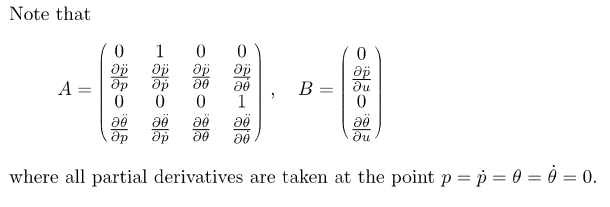

Queste matrici ci permettono di scrivere:


$$\left\lbrack \begin{array}{c}
\dot{\phi \;} \\
\ddot{\phi \;} \\
\dot{\theta \;} \\
\ddot{\theta \;} 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
\phi \\
\dot{\phi \;} \\
\theta \;\\
\dot{\theta \;} 
\end{array}\right\rbrack +\textrm{Bu}$$


Come prima cosa andiamo ad assegnare, al simbolo $\alpha \;,$ il valore 0.

phi2_differenziabile = subs(phi2_differenziabile,{alpha},{0});
theta2_differenziabile = subs(theta2_differenziabile,{alpha},{0});

Cerchiamo poi l'angolo in cui si ha l'equilibrio, ovvero quello in cui, con lo stato tutto posto a 0 (ovvero posizioni e velocità), si ottiene accelerazione nulla: da questo ne consegue quindi che il sistema risulta essere fermo.

NB: questo angolo è differente da 0, per la presenza dell'asta che sposta in avanti l'equilibrio del segway, che non è quindi più lungo la verticale.

NB2: abbiamo anche verificato che questo angolo *theta_equilibrio* sia uguale a 0 nel caso in cui l'asta del manubrio si trovi sopra la base (ovvero w_b = 0).

equilibri = solve(subs(theta2_differenziabile,{q_1 q_1_p q_2_p u},{0,0,0,0})==0,q_2)

$$equilibri = 0$$

La soluzione di questa equazione ritorna due posizioni di equilirbio: guardando i valori si nota che la parte complessa può essere trascurata, poichè prossima a zero.

Le due posizioni di equilibrio quindi sono

values_rad = real(equilibri); % [rad]
theta_equilibrio = values_rad(1)

$$theta\_equilibrio = 0$$

Andiamo a linearizzare intorno al seguente equilibrio.

equilibrio = {0,0,theta_equilibrio,0,0,0};
%equilibrio = {0,0,0,0,0};

**Definizione della matrice A:**

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),  {q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
A = double([A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44])

A =          0    1.0000         0         0
         0         0  -15.4581         0
         0         0         0    1.0000
         0         0    5.4729         0


**Definizione della matrice B:**

B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u u_star},equilibrio);
B = double([B11;B21;B31;B41])

B =          0
   -2.7639
         0
    0.2575


**Definizione della matrice C:**

%C = [0,0,1,0] % Riportiamo in uscita solamente l'angolo
C = eye(4); % Riportiamo in uscita tutte le variabili di stato

**Definizione della matrice D:**

D = zeros(4,1);

La procedura per la determinazione della funzione di trasferimento di un sistema, non strettamente proprio, è definita dalla relazione:


$$G\left(s\right)=C\bullet {\left(\textrm{sI}-A\right)}^{-1} \bullet B+D$$


syms s G(s);
G = (C*(s*eye(4)-A)^(-1)*B+D)

$$G = \left(\begin{array}{c} \frac{2464046135179261347236613881}{9007199254740992\,\left(376092903767\,s^{2}-68719476736\,s^{4}\right)}-\frac{6223714956017665}{2251799813685248\,s^{2}}\\ \frac{2464046135179261347236613881}{9007199254740992\,\left(376092903767\,s-68719476736\,s^{3}\right)}-\frac{6223714956017665}{2251799813685248\,s}\\ \frac{283154845433}{16\,\left(68719476736\,s^{2}-376092903767\right)}\\ \frac{283154845433\,s}{16\,\left(68719476736\,s^{2}-376092903767\right)} \end{array}\right)$$

## Salvataggio workspace

Andiamo a salvare il workspace per poterlo poi facilmente riutilizzare in fase di simulazione.

save('WS_VAB_wb_0_5.mat');